Example 1: 

                     (LP Pg 27 Q4)

A bacteria culture initially contains 100 cells and grows at a rate proportional to its size. After an error the population has increased to 420. 

(a) Find the number of bacteria after t hours. 

(b) Find the number of bacteria after 3 hours. 

(c) When will the population reach 10,000? 

(d) Graph the model.

%Equation
syms k t
y(t) = 100 * exp(k * t)

$$y(t) = 100\,{\mathrm{e}}^{k\,t}$$

eqn = y(1) == 420

$$eqn = 100\,{\mathrm{e}}^{k}=420$$

k = solve (eqn, k)

$$k = \log\left(\frac{21}{5}\right)$$

y (t) = simplify (subs (y(t)))

$$y(t) = \frac{100\,21^{t}}{5^{t}}$$


%Estimation
y_3 = round (double (y(3)))

y_3 = 7409

eqn = y(t) == 10000

$$eqn = \frac{100\,21^{t}}{5^{t}}=10000$$

t_10000 = double (solve (eqn, t))

t_10000 = 3.2090

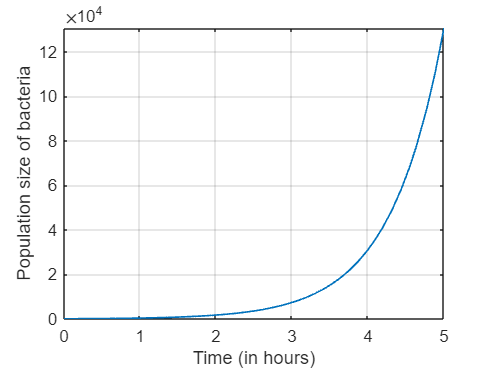


%Graph
fplot (y(t), [0 5], 'LineWidth', 1)
grid on
xlabel ('Time (in hours)')
ylabel ('Population size of bacteria')
hold off

Example 2:

                    (LP Pg 27 Q5)

Strontium-90 has a half life of 28 days.

(a) A sample has a mass of 50 mg initially. Find a formula for the mass remaining after t days.

(b) Find the mass remaining after 40 days.

(c) How long does it take for the sample to decay to a mass of 2 mg?

(d) Sketch the graph of the mass function.

%Equation
syms k t
y(t) = 50 * exp(k * t)

$$y(t) = 50\,{\mathrm{e}}^{k\,t}$$

eqn = y(28) == 25

$$eqn = 50\,{\mathrm{e}}^{28\,k}=25$$

k = solve (eqn, k)

$$k = -\frac{\log\left(2\right)}{28}$$

y (t) = simplify (subs (y(t)))

$$y(t) = \frac{50}{2^{t/28}}$$


%Estimation
y_40 = double (y(40))

y_40 = 18.5749

eqn = y(t) == 2

$$eqn = \frac{50}{2^{t/28}}=2$$

t_2 = double (solve (eqn, t))

t_2 = 130.0280

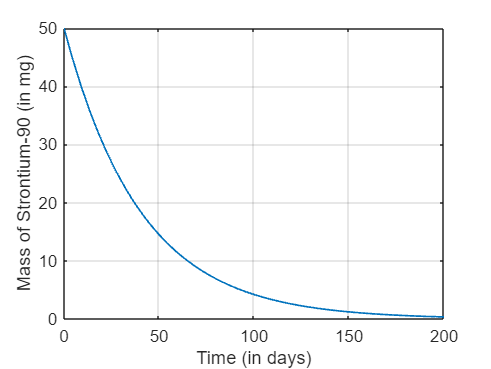


%Graph
fplot (y(t), [0 200], 'LineWidth', 1)
grid on
xlabel ('Time (in days)')
ylabel ('Mass of Strontium-90 (in mg)')
hold off

Example 3:

            (LP Pg 27 Q6)

The population of a region is growing exponentially. There were 40000000 people in 1980 (when t = 0) and 56000000 in 1990. Build a mathematical model for the population at any time t, in years.

(a) What will be the population in the year 2000?

(b) What is the doubling time?

%Equation
syms k t
P(t) = 4000000 * exp (k * t)

$$P(t) = 4000000\,{\mathrm{e}}^{k\,t}$$

eqn = P(1990) == 56000000

$$eqn = 4000000\,{\mathrm{e}}^{1990\,k}=56000000$$

k = solve (eqn, t)

 
k =
 
Empty sym: 0-by-1
 


P (t) = simplify (subs (P(t)))

 
P(t) =
 
Empty sym: 0-by-1
 



%Estimation
P_2000 = double (P(2000))


P_2000 =

  0×1 empty double column vector



eqn = P(t) == 80000000

 
eqn =
 
Empty sym: 0-by-1
 


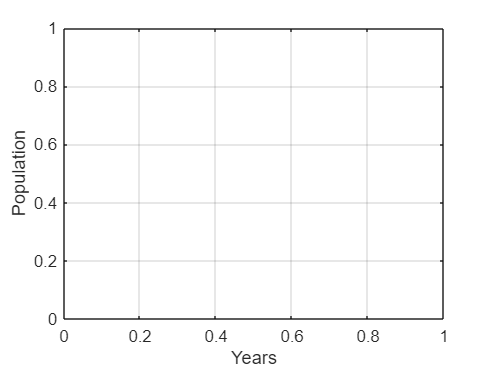

%t_80000000 = double (solve (eqn, t))

%Graph
fplot (P(t), [1980 2020], 'LineWidth', 1)
grid on
xlabel ('Years')
ylabel ('Population')
hold off